# PRACTICA 3: Compresi´on de señales 1D

## Ejercicio 1

#### Cargar una señal. Por ejemplo, pod´eis usar:

x=linspace(0,3,4096);
s=(x.^2).*((2-x).^2).*sin(8*pi*x).*(0<x&x<2) + 2*(2-x).*((3-x).^ 2).*sin(20*pi*x).*(2<x&x<3);

#### Hacer el an´alisis wavelet y comprimir conservando diferentes niveles de energ´ıa. Observar el n´umero de ceros en cada caso.

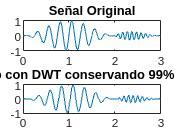

N de ceros después de la compr conservando 99% de la energía: 3919


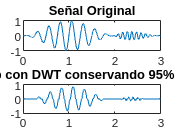

N de ceros después de la compr conservando 95% de la energía: 3990


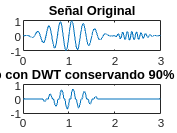

N de ceros después de la compr conservando 90% de la energía: 4046


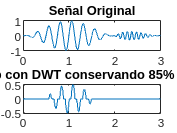

N de ceros después de la compr conservando 85% de la energía: 4072


% Análisis wavelet discreto utilizando la wavelet 'db1' (Daubechies con 1 cero)
[C, L] = wavedec(s, 4, 'db4');

% Niveles de energía a conservar
nivelesEnergia = [0.99, 0.95, 0.90, 0.85];

for nivel = nivelesEnergia
    % Compresión de la señal conservando el nivel de energía especificado
    energiaTotal = sum(C.^2);
    threshold = sqrt(energiaTotal) * (1 - sqrt(nivel));
    
    % Aplicación del umbral
    CThresholded = wthresh(C, 's', threshold);
    
    % Contar los ceros después de aplicar el umbral
    contadorCeros = numel(C) - nnz(CThresholded);
    
    % Reconstrucción de la señal a partir de los coeficientes umbralizados
    sComprimida = waverec(CThresholded, L, 'db1');
    
    % Visualización de la señal original y la señal comprimida
    figure;
    subplot(2,1,1);
    plot(x, s);
    title('Señal Original');
    subplot(2,1,2);
    plot(x, sComprimida);
    title(['Señal Comp con DWT conservando ', num2str(nivel*100), '% de la energía']);
    
    % Número de ceros después de la compresión
    disp(['N de ceros después de la compr conservando ', num2str(nivel*100), '% de la energía: ', num2str(contadorCeros)]);
end

#### Utilizar diferentes tipos de wavelets y distintos niveles de transformada. Observar por qu´e se recomienda para el nivel m´aximo.

Wavelet: db1, Nivel: 1, Ceros: 3611
Wavelet: db1, Nivel: 2, Ceros: 3791
Wavelet: db1, Nivel: 3, Ceros: 3880
Wavelet: db1, Nivel: 4, Ceros: 3967
Wavelet: db1, Nivel: 5, Ceros: 4009


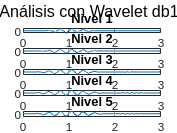

Wavelet: sym4, Nivel: 1, Ceros: 3616
Wavelet: sym4, Nivel: 2, Ceros: 3802
Wavelet: sym4, Nivel: 3, Ceros: 3896
Wavelet: sym4, Nivel: 4, Ceros: 3993
Wavelet: sym4, Nivel: 5, Ceros: 4048


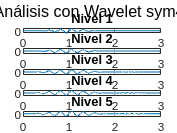

Wavelet: coif1, Nivel: 1, Ceros: 3614
Wavelet: coif1, Nivel: 2, Ceros: 3797
Wavelet: coif1, Nivel: 3, Ceros: 3889
Wavelet: coif1, Nivel: 4, Ceros: 3983
Wavelet: coif1, Nivel: 5, Ceros: 4039


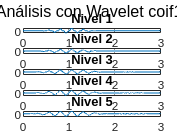

Wavelet: bior1.3, Nivel: 1, Ceros: 3615
Wavelet: bior1.3, Nivel: 2, Ceros: 3801
Wavelet: bior1.3, Nivel: 3, Ceros: 3894
Wavelet: bior1.3, Nivel: 4, Ceros: 3979
Wavelet: bior1.3, Nivel: 5, Ceros: 4030


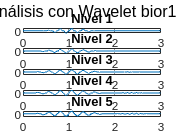

Wavelet: rbio1.3, Nivel: 1, Ceros: 3615
Wavelet: rbio1.3, Nivel: 2, Ceros: 3801
Wavelet: rbio1.3, Nivel: 3, Ceros: 3894
Wavelet: rbio1.3, Nivel: 4, Ceros: 3980
Wavelet: rbio1.3, Nivel: 5, Ceros: 4041


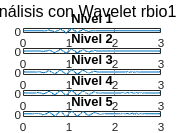

% Tipos de wavelets a utilizar
wavelets = {'db1', 'sym4', 'coif1', 'bior1.3', 'rbio1.3'};
% Niveles de descomposición a considerar
niveles = 1:5;

% Crear una figura para cada wavelet
for wname = wavelets
    figure;
    sgtitle(['Análisis con Wavelet ', char(wname)]);
    
    for nivel = niveles
        % Análisis wavelet discreto
        [C, L] = wavedec(s, nivel, char(wname));
        
        % Compresión de la señal conservando el 95% de la energía
        energiaTotal = sum(C.^2);
        threshold = sqrt(energiaTotal) * (1 - sqrt(0.95));
        
        % Aplicación del umbral
        CThresholded = wthresh(C, 's', threshold);
        
        % Reconstrucción de la señal a partir de los coeficientes umbralizados
        sComprimida = waverec(CThresholded, L, char(wname));
        
        % Visualización de la señal comprimida en un subplot
        subplot(5, 1, nivel);
        plot(x, sComprimida);
        title(['Nivel ', num2str(nivel)]);
        
        % Número de ceros después de la compresión
        contadorCeros = numel(C) - nnz(CThresholded);
        disp(['Wavelet: ', char(wname), ', Nivel: ', num2str(nivel), ', Ceros: ', num2str(contadorCeros)]);
    end
end

#### Para el umbralizado, probar con el m´etodo de “Global threshold”. Intentar mejorar el n´umero de ceros usando “By level thresholding” visualmente.

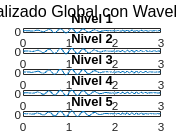

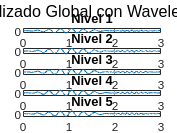

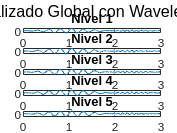

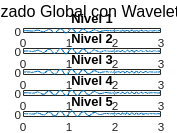

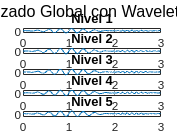

% Tipos de wavelets a utilizar
wavelets = {'db1', 'sym4', 'coif1', 'bior1.3', 'rbio1.3'};
% Niveles de descomposición a considerar
niveles = 1:5;

% Umbral global basado en la regla de Donoho-Johnstone
sigma = mad(C, 1) / 0.6745;
thresholdGlobal = sigma * sqrt(2*log(numel(s)));

for wname = wavelets
    figure;
    sgtitle(['Umbralizado Global con Wavelet ', char(wname)]);
    
    for nivel = niveles
        % Análisis wavelet discreto
        [C, L] = wavedec(s, nivel, char(wname));
        
        % Aplicación del umbral global
        CThresholded = wthresh(C, 's', thresholdGlobal);
        
        % Reconstrucción de la señal a partir de los coeficientes umbralizados
        sComprimida = waverec(CThresholded, L, char(wname));
        
        % Visualización de la señal comprimida en un subplot
        subplot(5, 1, nivel);
        plot(x, sComprimida);
        title(['Nivel ', num2str(nivel)]);
    end
end

#### Probar con algunas de las señales de audio: wellcome.wav, speech.wav

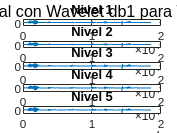

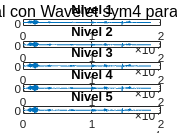

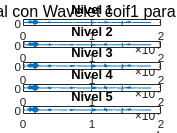

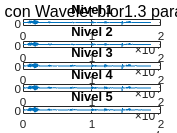

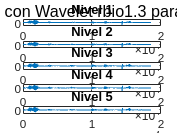

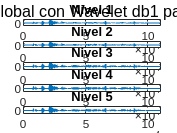

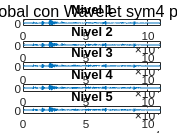

% Lista de archivos de audio a analizar
archivosAudio = {'WELLCOME.WAV', 'speech.wav'};

% Tipos de wavelets a utilizar
wavelets = {'db1', 'sym4', 'coif1', 'bior1.3', 'rbio1.3'};
% Niveles de descomposición a considerar
niv = 1:5;

for i = 1:length(archivosAudio)
    % Acceder al archivo de audio actual
    archivo = archivosAudio{i};
    
    % Leer la señal de audio
    [s, fs] = audioread(archivo);
    
    % Umbral global basado en la regla de Donoho-Johnstone
    sigma = mad(s, 1) / 0.6745;
    umbralGlobal = sigma * sqrt(2*log(numel(s)));
    
    for wname = wavelets
        figure;
        sgtitle(['Umbralizado Global con Wavelet ', char(wname), ' para ', char(archivo)]);
        
        for n = niv
            % Análisis wavelet discreto
            [C, L] = wavedec(s, n, char(wname));
            
            % Aplicación del umbral global
            CUmbral = wthresh(C, 's', umbralGlobal);
            
            % Reconstrucción de la señal a partir de los coeficientes umbralizados
            sComp = waverec(CUmbral, L, char(wname));
            
            % Visualización de la señal comprimida en un subplot
            subplot(5, 1, n);
            plot(sComp);
            title(['Nivel ', num2str(n)]);
        end
    end
end

## Ejercicio 2

### Escribir un Live Script (un c´odigo .mlx) de Matlab para realizar la compresi´on de una señal 1D. El c´odigo debe hacer:

#### 1. Cargar la señal

[s, fs] = audioread('speech.wav');

#### 2. Como variables poner el tipo de wavelet, el nivel de descomposici´on, el nivel de energ´ıa conservada y el tipo de umbralizado.

tipo_wavelet = 'db3'; % Tipo de wavelet
nivel_descomposicion = 7; % Nivel de descomposición
energia_conservada = 0.9; % Nivel de energía conservada en porcentaje
tipo_umbralizado = 's'; % Tipo de umbralizado ('s' para suave, 'h' para duro)

#### 3. Calcular la transformada wavelet.

[C, L] = wavedec(s, nivel_descomposicion, tipo_wavelet);

#### 4. Reordenar los valores de la transformada el orden de valor absoluto decreciente (usar el comando sort, ’descend’).

[C_order, C_indice] = sort(abs(C), 'descend');

#### 5. Calcular el perfil de energ´ıa acumulada usando la transformada reordenada (cumenergy).

energia_acumulada = cumenergy(C_order);

#### 6. Representar los perfiles de energ´ıa acumulada para la señal, la transformada y la reordenada.

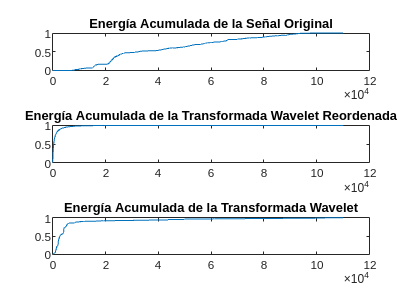

figure;
subplot(3,1,1);
plot(cumenergy(s));
title('Energía Acumulada de la Señal Original');
subplot(3,1,2);
plot(energia_acumulada);
title('Energía Acumulada de la Transformada Wavelet Reordenada');
subplot(3,1,3);
plot(cumenergy(C));
title('Energía Acumulada de la Transformada Wavelet');

#### 7. Calcular el umbral con el dato sobre la energ´ıa que se quiere conservar (find).

umbral = find(energia_acumulada <= energia_conservada,1);

#### 8. Umbralizar la transformada sin reordenar, se puede usar el comando wthresh.

C_umbral = wthresh(C, tipo_umbralizado, umbral);

#### 9. Reconstruir la señal (transformada inversa).

s_reconstruida = waverec(C_umbral, L, tipo_wavelet);

#### 10. Representar gr´aficamente las señales original y reconstruida. O reproducir los audios de ambas señales.

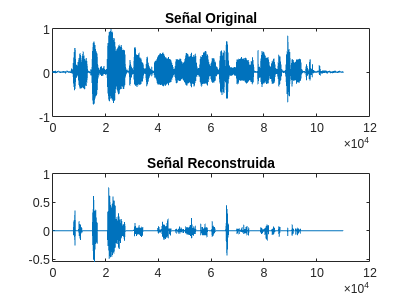

figure;
subplot(2,1,1);
plot(s);
title('Señal Original');
subplot(2,1,2);
plot(s_reconstruida);
title('Señal Reconstruida');

#### 11. Comparar los resultados visualmente y calcular el error entre la señal original y la reconstruida (usar la funci´on wrms).

error = sqrt(mean((s - s_reconstruida).^2));

#### 12. Contar el n´umero de nulos y no nulos, con el comando nnz. Calcular el factor de compresi´on de la señal (n´umero de datos no nulos dividido por el numero original N:M).

num_no_nulos = nnz(C_umbral);
num_nulos = length(C_umbral) - num_no_nulos;
factor_compresion = num_no_nulos / length(s);

% Mostrar resultados
disp(['Error WRMS: ', num2str(error)]);

Error WRMS: 0.11093


disp(['Factor de Compresión: ', num2str(factor_compresion)]);

Factor de Compresión: 0.0045623


## Ejercicio 3

#### Usando el c´odigo del ejercicio anterior comprimir cada una de las señales unidimensionales de abajo conservando el 99.99 %, el 99.00 % y el 95.00 % de la energ´ıa. Utilizar diferentes tipos de wavelets y el nivel m´aximo de descomposici´on wavelet. Señales para el 

Error WRMS con Wavelet haar, Energía Conservada al 99.990000% y Nivel de Descomposición 16: 0.003967
Factor de Compresión con Wavelet haar, Energía Conservada al 99.990000% y Nivel de Descomposición 16: 0.593697


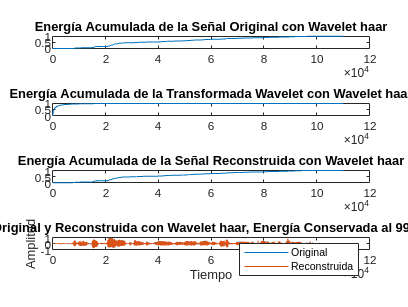

Error WRMS con Wavelet haar, Energía Conservada al 99.000000% y Nivel de Descomposición 16: 0.024377
Factor de Compresión con Wavelet haar, Energía Conservada al 99.000000% y Nivel de Descomposición 16: 0.175525


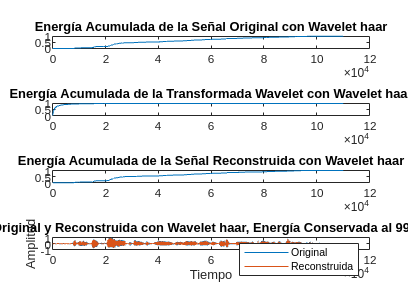

Error WRMS con Wavelet haar, Energía Conservada al 95.000000% y Nivel de Descomposición 16: 0.047281
Factor de Compresión con Wavelet haar, Energía Conservada al 95.000000% y Nivel de Descomposición 16: 0.070610


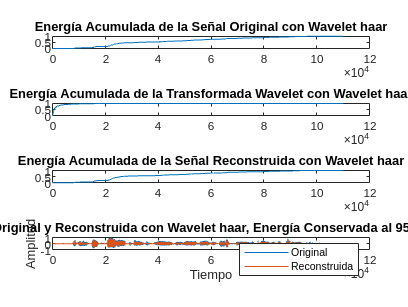

Error WRMS con Wavelet db2, Energía Conservada al 99.990000% y Nivel de Descomposición 15: 0.003413
Factor de Compresión con Wavelet db2, Energía Conservada al 99.990000% y Nivel de Descomposición 15: 0.462492


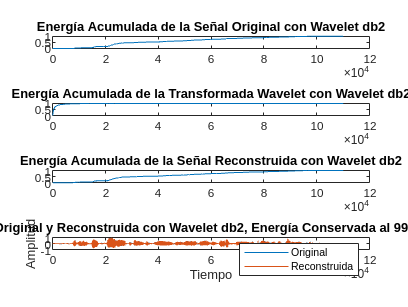

Error WRMS con Wavelet db2, Energía Conservada al 99.000000% y Nivel de Descomposición 15: 0.024584
Factor de Compresión con Wavelet db2, Energía Conservada al 99.000000% y Nivel de Descomposición 15: 0.116209


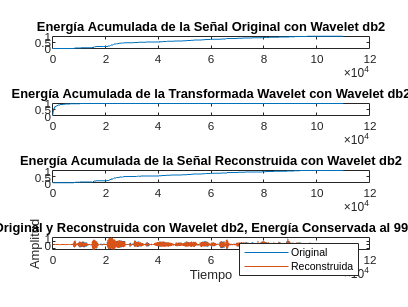

Error WRMS con Wavelet db2, Energía Conservada al 95.000000% y Nivel de Descomposición 15: 0.046969
Factor de Compresión con Wavelet db2, Energía Conservada al 95.000000% y Nivel de Descomposición 15: 0.046843


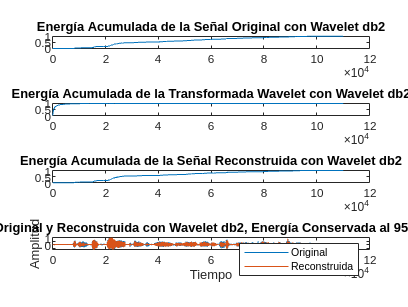

Error WRMS con Wavelet db3, Energía Conservada al 99.990000% y Nivel de Descomposición 14: 0.003280
Factor de Compresión con Wavelet db3, Energía Conservada al 99.990000% y Nivel de Descomposición 14: 0.427867


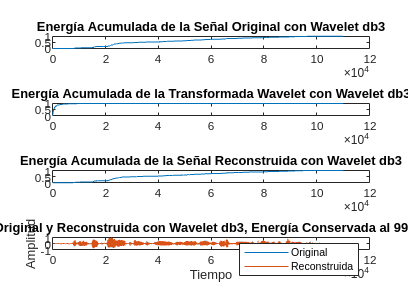

Error WRMS con Wavelet db3, Energía Conservada al 99.000000% y Nivel de Descomposición 14: 0.024477
Factor de Compresión con Wavelet db3, Energía Conservada al 99.000000% y Nivel de Descomposición 14: 0.103038


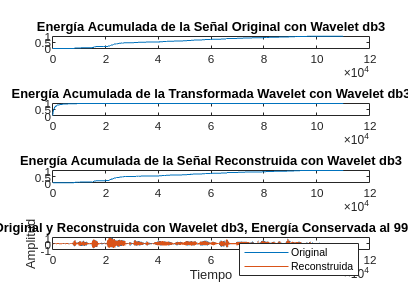

Error WRMS con Wavelet db3, Energía Conservada al 95.000000% y Nivel de Descomposición 14: 0.046959
Factor de Compresión con Wavelet db3, Energía Conservada al 95.000000% y Nivel de Descomposición 14: 0.041628


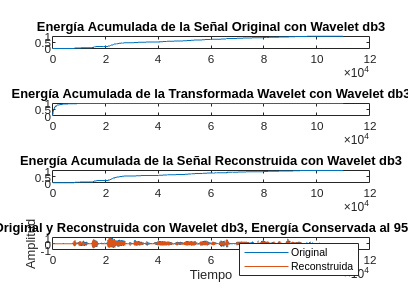

Error WRMS con Wavelet haar, Energía Conservada al 99.990000% y Nivel de Descomposición 14: 0.004650
Factor de Compresión con Wavelet haar, Energía Conservada al 99.990000% y Nivel de Descomposición 14: 0.624524


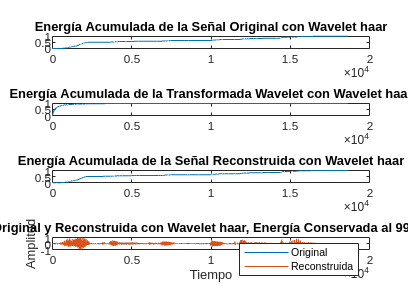

Error WRMS con Wavelet haar, Energía Conservada al 99.000000% y Nivel de Descomposición 14: 0.024784
Factor de Compresión con Wavelet haar, Energía Conservada al 99.000000% y Nivel de Descomposición 14: 0.215977


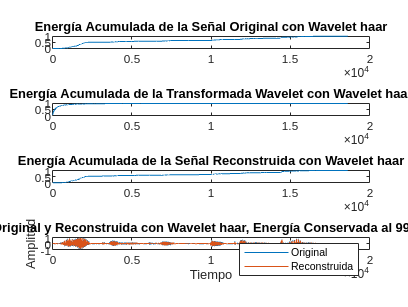

Error WRMS con Wavelet haar, Energía Conservada al 95.000000% y Nivel de Descomposición 14: 0.047432
Factor de Compresión con Wavelet haar, Energía Conservada al 95.000000% y Nivel de Descomposición 14: 0.087829


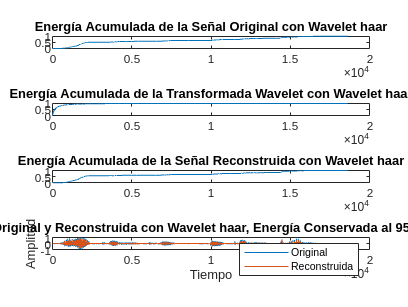

Error WRMS con Wavelet db2, Energía Conservada al 99.990000% y Nivel de Descomposición 12: 0.003916
Factor de Compresión con Wavelet db2, Energía Conservada al 99.990000% y Nivel de Descomposición 12: 0.605576


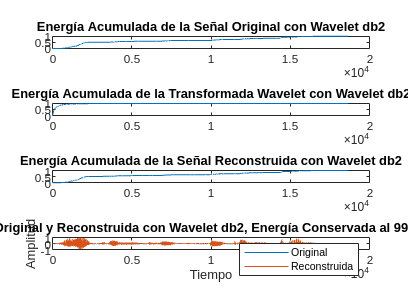

Error WRMS con Wavelet db2, Energía Conservada al 99.000000% y Nivel de Descomposición 12: 0.023524
Factor de Compresión con Wavelet db2, Energía Conservada al 99.000000% y Nivel de Descomposición 12: 0.156461


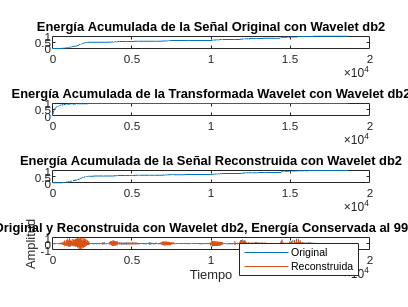

Error WRMS con Wavelet db2, Energía Conservada al 95.000000% y Nivel de Descomposición 12: 0.047408
Factor de Compresión con Wavelet db2, Energía Conservada al 95.000000% y Nivel de Descomposición 12: 0.061394


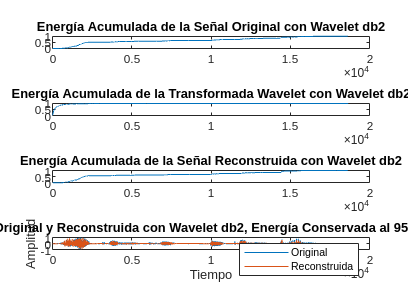

Error WRMS con Wavelet db3, Energía Conservada al 99.990000% y Nivel de Descomposición 11: 0.003647
Factor de Compresión con Wavelet db3, Energía Conservada al 99.990000% y Nivel de Descomposición 11: 0.586855


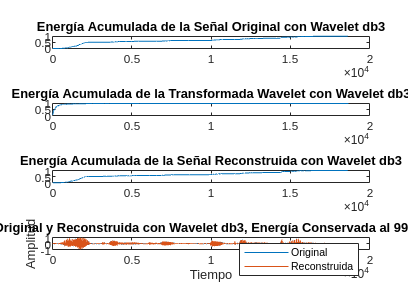

Error WRMS con Wavelet db3, Energía Conservada al 99.000000% y Nivel de Descomposición 11: 0.023457
Factor de Compresión con Wavelet db3, Energía Conservada al 99.000000% y Nivel de Descomposición 11: 0.142536


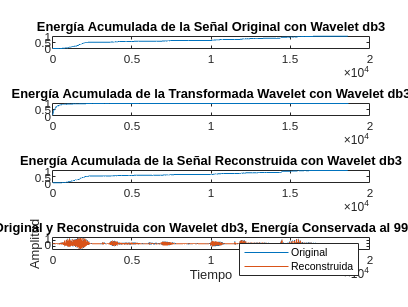

Error WRMS con Wavelet db3, Energía Conservada al 95.000000% y Nivel de Descomposición 11: 0.047250
Factor de Compresión con Wavelet db3, Energía Conservada al 95.000000% y Nivel de Descomposición 11: 0.053297


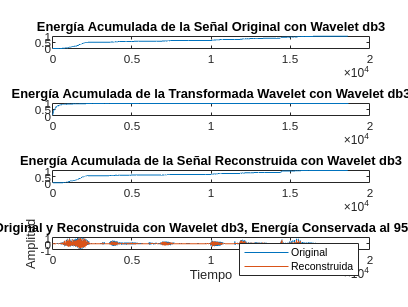

nombres_audios = {'speech.wav', 'WELLCOME.WAV'};
tipos_wavelet = {'haar', 'db2', 'db3'};
energias_conservadas = [0.9999, 0.9900, 0.9500];

for i = 1:length(nombres_audios)
    for j = 1:length(tipos_wavelet)
        for k = 1:length(energias_conservadas)
            [error, factor_compresion, s_reconstruida] = comprimir_audio(nombres_audios{i}, tipos_wavelet{j}, energias_conservadas(k));
            % Los gráficos se mostrarán automáticamente al ejecutar la función
        end
    end
end

## FUNCIONES

function [error, factor_compresion, s_reconstruida] = comprimir_audio(nombre_audio, tipo_wavelet, energia_conservada)
    % Cargar la señal de audio
    [s, fs] = audioread(nombre_audio);
    
    % Nivel máximo de descomposición wavelet
    nivel_descomposicion = wmaxlev(length(s), tipo_wavelet);
    
    % Calcular la transformada wavelet
    [C, L] = wavedec(s, nivel_descomposicion, tipo_wavelet);
    
    % Reordenar los coeficientes de la transformada wavelet
    [C_order, ~] = sort(abs(C), 'descend');
    
    % Calcular el perfil de energía acumulada
    energia_acumulada = cumsum(C_order.^2) / sum(C_order.^2);
    
    % Determinar el umbral para conservar el porcentaje deseado de energía
    umbral = C_order(find(energia_acumulada >= energia_conservada, 1));
    
    % Umbralizar los coeficientes
    C_umbral = wthresh(C, 's', umbral);
    
    % Reconstruir la señal
    s_reconstruida = waverec(C_umbral, L, tipo_wavelet);
    
    % Calcular el error WRMS y el factor de compresión
    error = sqrt(mean((s - s_reconstruida).^2));
    factor_compresion = nnz(C_umbral) / length(C);
    
    % Mostrar resultados
    fprintf('Error WRMS con Wavelet %s, Energía Conservada al %f%% y Nivel de Descomposición %d: %f\n', tipo_wavelet, energia_conservada*100, nivel_descomposicion, error);
    fprintf('Factor de Compresión con Wavelet %s, Energía Conservada al %f%% y Nivel de Descomposición %d: %f\n', tipo_wavelet, energia_conservada*100, nivel_descomposicion, factor_compresion);
    
    % Graficar la energía acumulada de la señal original
    figure;
    subplot(4,1,1);
    plot(cumsum(s.^2) / sum(s.^2));
    title(sprintf('Energía Acumulada de la Señal Original con Wavelet %s', tipo_wavelet));
    
    % Graficar la energía acumulada de la transformada wavelet
    subplot(4,1,2);
    plot(energia_acumulada);
    title(sprintf('Energía Acumulada de la Transformada Wavelet con Wavelet %s', tipo_wavelet));
    
    % Graficar la energía acumulada de la señal reconstruida
    subplot(4,1,3);
    plot(cumsum(s_reconstruida.^2) / sum(s_reconstruida.^2));
    title(sprintf('Energía Acumulada de la Señal Reconstruida con Wavelet %s', tipo_wavelet));
    
    % Graficar las señales original y reconstruida
    subplot(4,1,4);
    plot(s);
    hold on;
    plot(s_reconstruida);
    title(sprintf('Señal Original y Reconstruida con Wavelet %s, Energía Conservada al %f%%', tipo_wavelet, energia_conservada*100));
    xlabel('Tiempo');
    ylabel('Amplitud');
    legend('Original', 'Reconstruida');
    hold off;
end